**Assignment 1**

**Part1**

clc
clear all
%% Boundary Value Problem (BVP)
% Symbolic variables
syms E A rho L g s real % Constants
syms x u(x) r(x) q real %Variables

syms epsilon sigma real % Others

% Constants definitions

rho=pi^3/L^2;
s=g*pi^4/L^2;
F=A*E*g*pi^2/L;
r=(x/L)^2;

% Distributed force
q=E*(rho*u-s*r);

%Hooke's law
epsilon=diff(u,x);
sigma=E*epsilon;

% Equilibrium
eq1 = diff(sigma,x)+q==0;

% Boundary conditions
cond1 = u(0) == -g; % Displacement 
du_dx_L = diff(u,x);
cond2 = A*E*subs(du_dx_L,x,L) == F; %Force

% General solution 
u_sol = dsolve(eq1, cond1, cond2);
u_sol_simp = vpa(u_sol,4)

$$u\_sol\_simp = 1.545\,g\,\sin\left(\frac{5.568\,x}{L}\right)-0.7974\,g\,\cos\left(\frac{5.568\,x}{L}\right)-0.2026\,g+\frac{3.142\,g\,x^{2}}{L^{2}}$$

%% Exact Solution
% Apply numeric values
L_val=1;
g_val=0.01;

% Substitute
u_sol_val=(subs(u_sol,[g L], [g_val, L_val]));
u_sol_val_simp=vpa(u_sol_val,4)

$$u\_sol\_val\_simp = 0.01545\,\sin\left(5.568\,x\right)-0.007974\,\cos\left(5.568\,x\right)+0.03142\,x^{2}-0.002026$$

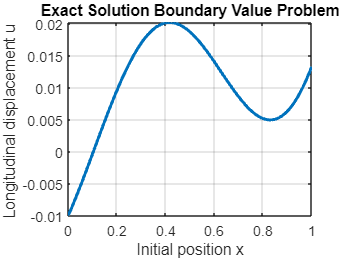


% Plotear la solución
fplot(u_sol_val_simp, [0 L_val], 'LineWidth',2)
xlabel('Initial position x')
ylabel('Longitudinal displacement u ')
grid on
title('Exact Solution Boundary Value Problem')